[https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

data = readtable('../data/data1/logvRNA.csv');

patients = unique(data.patient,'stable');
patients

patients = 6×1 cell array
    {'CHID46'}
    {'CHID77'}
    {'CHID79'}
    {'CHID32'}
    {'CHID40'}
    {'CHID08'}


num_pat = size(patients,1);



x1 = [2.0209E-7, 1.2719E-7, 0.41184, 1.52453, 41085.62299, 0.03901, 6];
x2 = [4.1205E-7, 9.9623E-8, 0.03291, 0.51576, 11563.55961, 0.02501, 6];
x3 = [2.0301E-7, 8.4588E-16, 0.0132, 0.97946, 29382.88451, 0.03439, 10];
x4 = [1.1951E-6, 9.2262E-7, 0.43713, 4.15686, 10980.08977, 0.10254, 13];
x5 = [2.9663E-7, 2.0198E-7, 0.18906, 1.34474, 23745.98087, 0.03773, 6];
x6 = [2.0375E-8, 1.0302E-7, 0.1101, 5.23275, 781644.29827, 3.9911E-17, 21];


% xx1 = [0.409*10^-6, 0.233*10^-6, 0.249, 0.775, 14.5*10^3, 0.03, 7];
% xx2 = [0.431*10^-6, 0.140*10^-6, 0.077, 0.420, 10*10^3, 0.021, 24];
% xx3 = [0.201*10^-6, 0.001*10^-6, 0.013, 1.048, 30.172*10^3, 0.036, 10];
% xx4 = [9.203E-6, 0.011E-6, 0.013, 0.851, 0.548E3, 0.055, 12];
% xx5 = [0.485E-6, 0.291E-6, 0.096, 0.803, 11.425E3, 0.033, 5];
% xx6 = [0.057E-6, 0.004E-6, 0.021, 0.821, 89.892E3, 0.003, 22];


x = [x1;x2;x3;x4;x5;x6];
% xx = [xx1,xx2,xx3,xx4,xx5,xx6,xx1];


best_params = zeros(num_pat,7);

tic

for i = 1:num_pat
    p = patients(i);
    path = string(strcat('../data/data1/',patients(i),'.csv'))
    data_p = table2array(readtable(path));

    param = x(1,:);

    best_params(i,:) = [best_param(data_p,param), param(end)];
end 

path = "../data/data1/CHID46.csv"

path = "../data/data1/CHID77.csv"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.118187 



path = "../data/data1/CHID79.csv"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.054417 



path = "../data/data1/CHID32.csv"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.418730 



path = "../data/data1/CHID40.csv"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.010709 



path = "../data/data1/CHID08.csv"

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.040370 




toc

Elapsed time is 222.769801 seconds.


param_tb = array2table(best_params,...
            'VariableNames', ...
            {'beta0','beta_infty','k','dlt','p','d','tau'})

param_tb = 6×7 table
      beta0       beta_infty       k          dlt        p          d        tau
    __________    __________    ________    _______    _____    _________    ___

    2.0182e-07    1.2746e-07     0.37939     1.5309    40961     0.039217     6 
    2.3713e-07    1.3038e-07     0.42812     1.7868    39438     0.020316     6 
    1.0581e-07     3.966e-08     0.02267     1.6578    73751     0.049787     6 
    2.1072e-07    2.1073e-07    -0.35035     3.1924    50044     0.049119     6 
    2.3216e-07    1.6102e-07     0.56892      1.816    37744     0.038619     6 
    6.4505e-08     6.123e-08      4.7649    0.38602    68520    -0.031837     6 



writetable(param_tb, 'best_params_mat.csv')

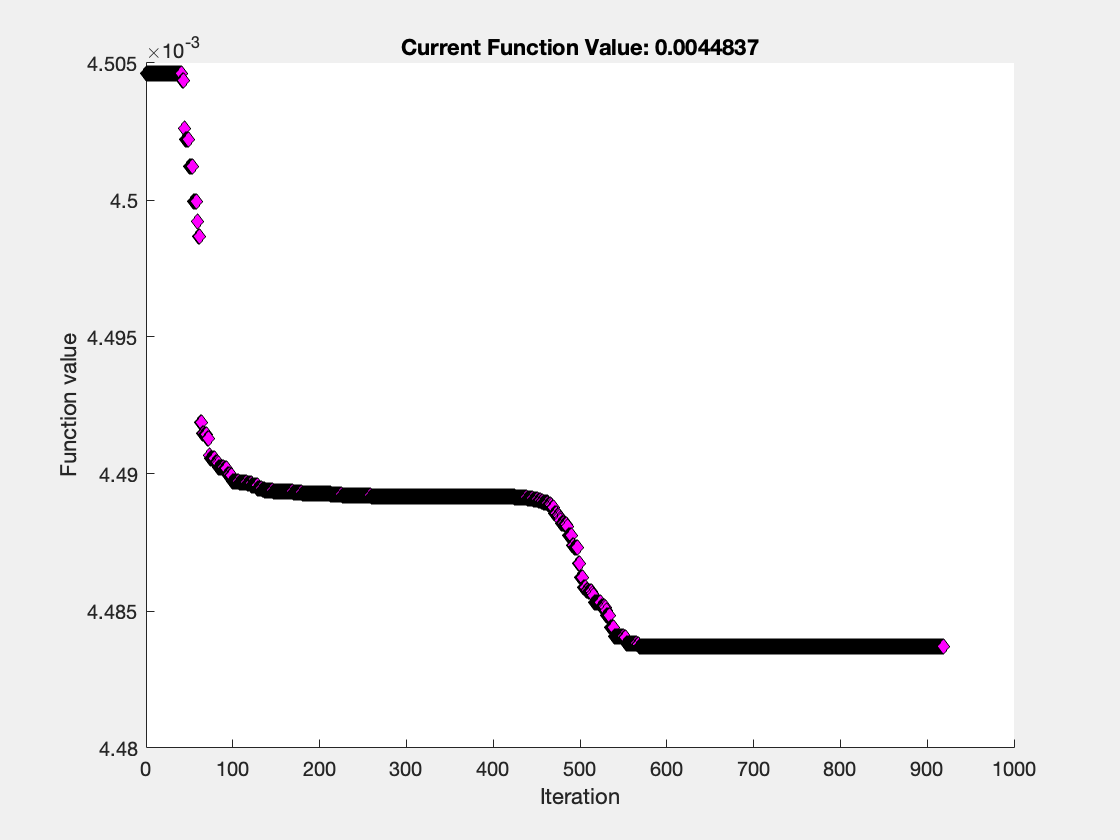

% tic
% 
% JJ = @(param) J(param, data, h,time,init,tau,c);
% 
% % options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
% 
% x0 = [2.0187*(10^-7),1.2535*(10^-7),1.42261,1.56561,42.77631622*(10^3),0.03931];
% [x,fval] = fminsearch(JJ,x0,options);

% x

x = 1.0e+04 *

    0.0000    0.0000    0.0001    0.0002    4.2408    0.0000


% 
% toc

Elapsed time is 65.124073 seconds.


% % +-10% error

fval = 0.0045

% plot(time, pred_logV(x,time,init, 7,23), ...
%     time,pred_logV(x0,time,init, 7,23), ...
%     time,pred_logV(xx,time,init, 7,23))
% 
% disp([JJ(x),JJ(x0),JJ(xx)]);
% hold on;
% scatter(data.dpi,data.log_vRNA);
% hold off;
% legend({'x','x0','xx'},'Location','southwest')

size(x1(1:end-1))

ans =      1     6


function out=beta(t,tau,k,beta_0,beta_ifty)
    if t <= tau
        out = beta_0;
    else
        out = beta_ifty+(beta_0-beta_ifty)*exp(-k*(t-tau));
    end
end


function out = pred_logV(param, time, init,tau,c)
    beta_0=param(1);
    beta_ifty=param(2);
    k = param(3);
    dlt = param(4);
    p = param(5);
    d = param(6);
    
    f = @(t,x) [d*(10^4-x(1))-beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3);...
            beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-c*x(3) ];
  
    [t,xa] = ode45(f,time,init);
    out = log10(xa(:,3));
    
end


function out=J(param,data,h,time,init,tau,c)
    pred = pred_logV(param, time, init,tau,c);

    num = size(data,1);
    sum = 0;
    for i = 1:num
        day = data(i,1);
        pred_logv = pred(day/h+1);
        
        sum = sum + (pred_logv - data(i,2))^2;
    end 
    
   out = sum/num;
end 

function out=best_param(data,x0)
    h = 0.01;
    time = 0:h:80; 
    init = [10^4 0 10^-3];
    c = 23;
    tau = x0(end);

    % options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
    JJ = @(param) J(param, data, h,time,init,tau,c);
    out = fminsearch(JJ,x0(1:end-1));
end 